# **Assignment**

## **Introduction**

**How to use the template**

There are many organize and communicate your results. To help ensure your peer-reviewers can accurately grade your report, this report includes the titles for the 4 required sections in Heading 1 style. Each required element for a given section has a Heading 2 area for you to place the final result. 

Make sure to place your required findings in the appropiate area for your peer-reviewer to easily find them.

Also, only the heading titles are present.* The script is not broken into sections*.

### Background and Scope

### Import the Data

You may use an import function. If not using an import function, include the code used to import the data (it may be generated from the Import Tool)

uiimport("StormEvents_2017_finalProject.csv")

StormEvents2017finalProject

StormEvents2017finalProject = 57005×24 table
    EpisodeID      Event_ID         State         Year     Month            Event_Type                               CZ_Name                           Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                             

### Two States Most Impacted by Harvey

Clearly state the two states in order 

Texas

Puerto Rico

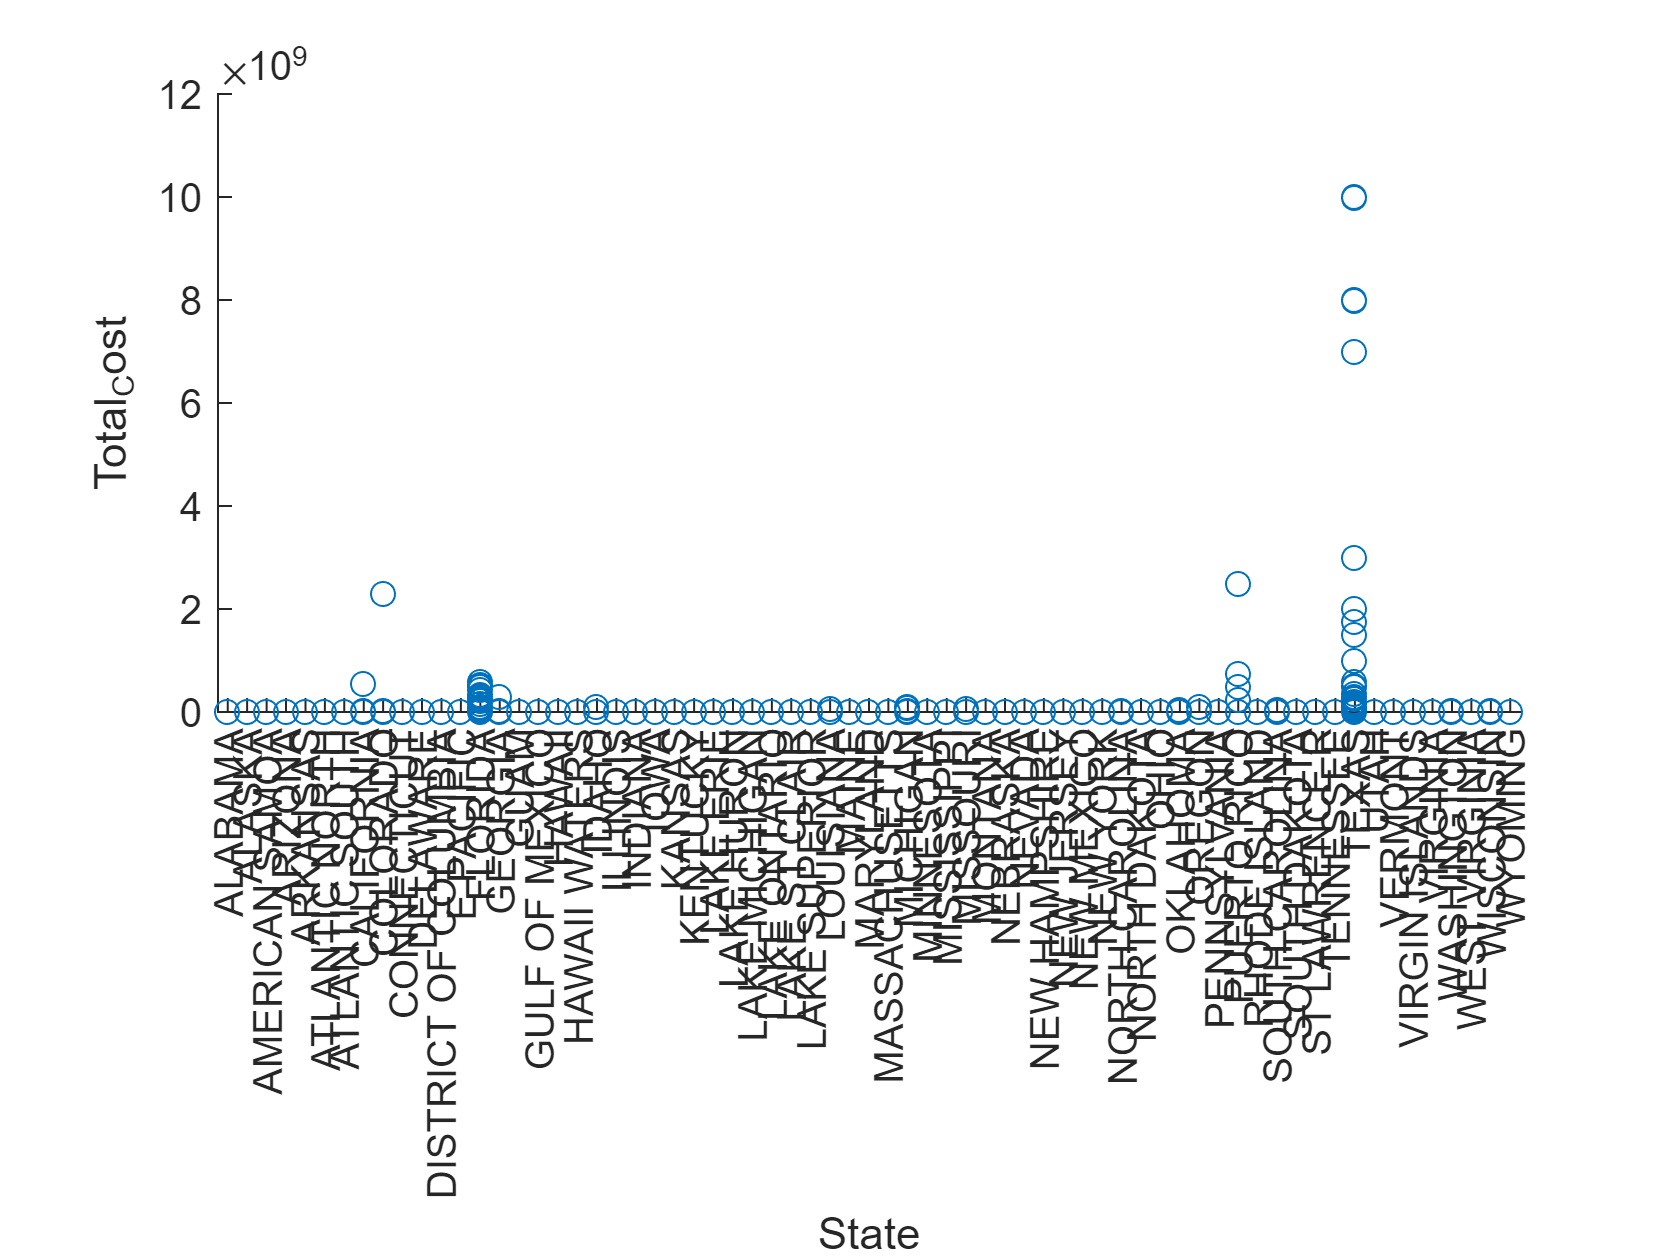

Data1 = StormEvents2017finalProject;
Data1.Property_Cost(ismissing(Data1.Property_Cost))=0;
Data1.Crop_Cost(ismissing(Data1.Crop_Cost)) = 0;
Data1.Total_Cost = Data1.Property_Cost+Data1.Crop_Cost;
scatter(Data1,"State","Total_Cost")

### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

Data2 = Data1(Data1.State =="TEXAS" | Data1.State == "PUERTO RICO",:);
[PR_Loss, id1]= maxk(Data2.Total_Cost(Data2.State == "PUERTO RICO"),5);
PR_Event_Type = Data2.Event_Type(id1);
[TX_Loss, id2]= maxk(Data2.Total_Cost(Data2.State == "TEXAS"),5);
TX_Event_Type = Data2.Event_Type(id2);
table(PR_Loss,PR_Event_Type,TX_Loss,TX_Event_Type)

ans = 5×4 table
    PR_Loss      PR_Event_Type      TX_Loss      TX_Event_Type  
    _______    _________________    _______    _________________

    2.5e+09    Thunderstorm Wind     1e+10     Thunderstorm Wind
    7.5e+08    Thunderstorm Wind     1e+10     Lightning        
    7.5e+08    Hail                  1e+10     Hail             
    7.5e+08    Thunderstorm Wind     8e+09     Thunderstorm Wind
    7.5e+08    Thunderstorm Wind     8e+09     Thunderstorm Wind


## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

Data2

Data2 = 3850×25 table
    EpisodeID      Event_ID     State    Year     Month        Event_Type         CZ_Name       Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                 Episode_Narrative                                                                        


Data2.Event_Type = removecats(Data2.Event_Type,{'Avalanche','Dense Fog','Dense Smoke','Dust Devil','Freezing Fog','Lake-Effect Snow','Lakeshore Flood','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Sleet','Tropical Depression','Waterspout'});
Data2.Event_Type = mergecats(Data2.Event_Type,{'Less Frequent Events','Debris Flow','Dust Storm','Extreme Cold/Wind Chill','High Surf','Sneakerwave','Astronomical Low Tide','Blizzard','Cold/Wind Chill','Winter Storm','Ice Storm','Storm Surge/Tide','Coastal Flood','Strong Wind'})

Data2 = 3850×25 table
    EpisodeID      Event_ID     State    Year     Month        Event_Type         CZ_Name       Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                 Episode_Narrative                                                                        

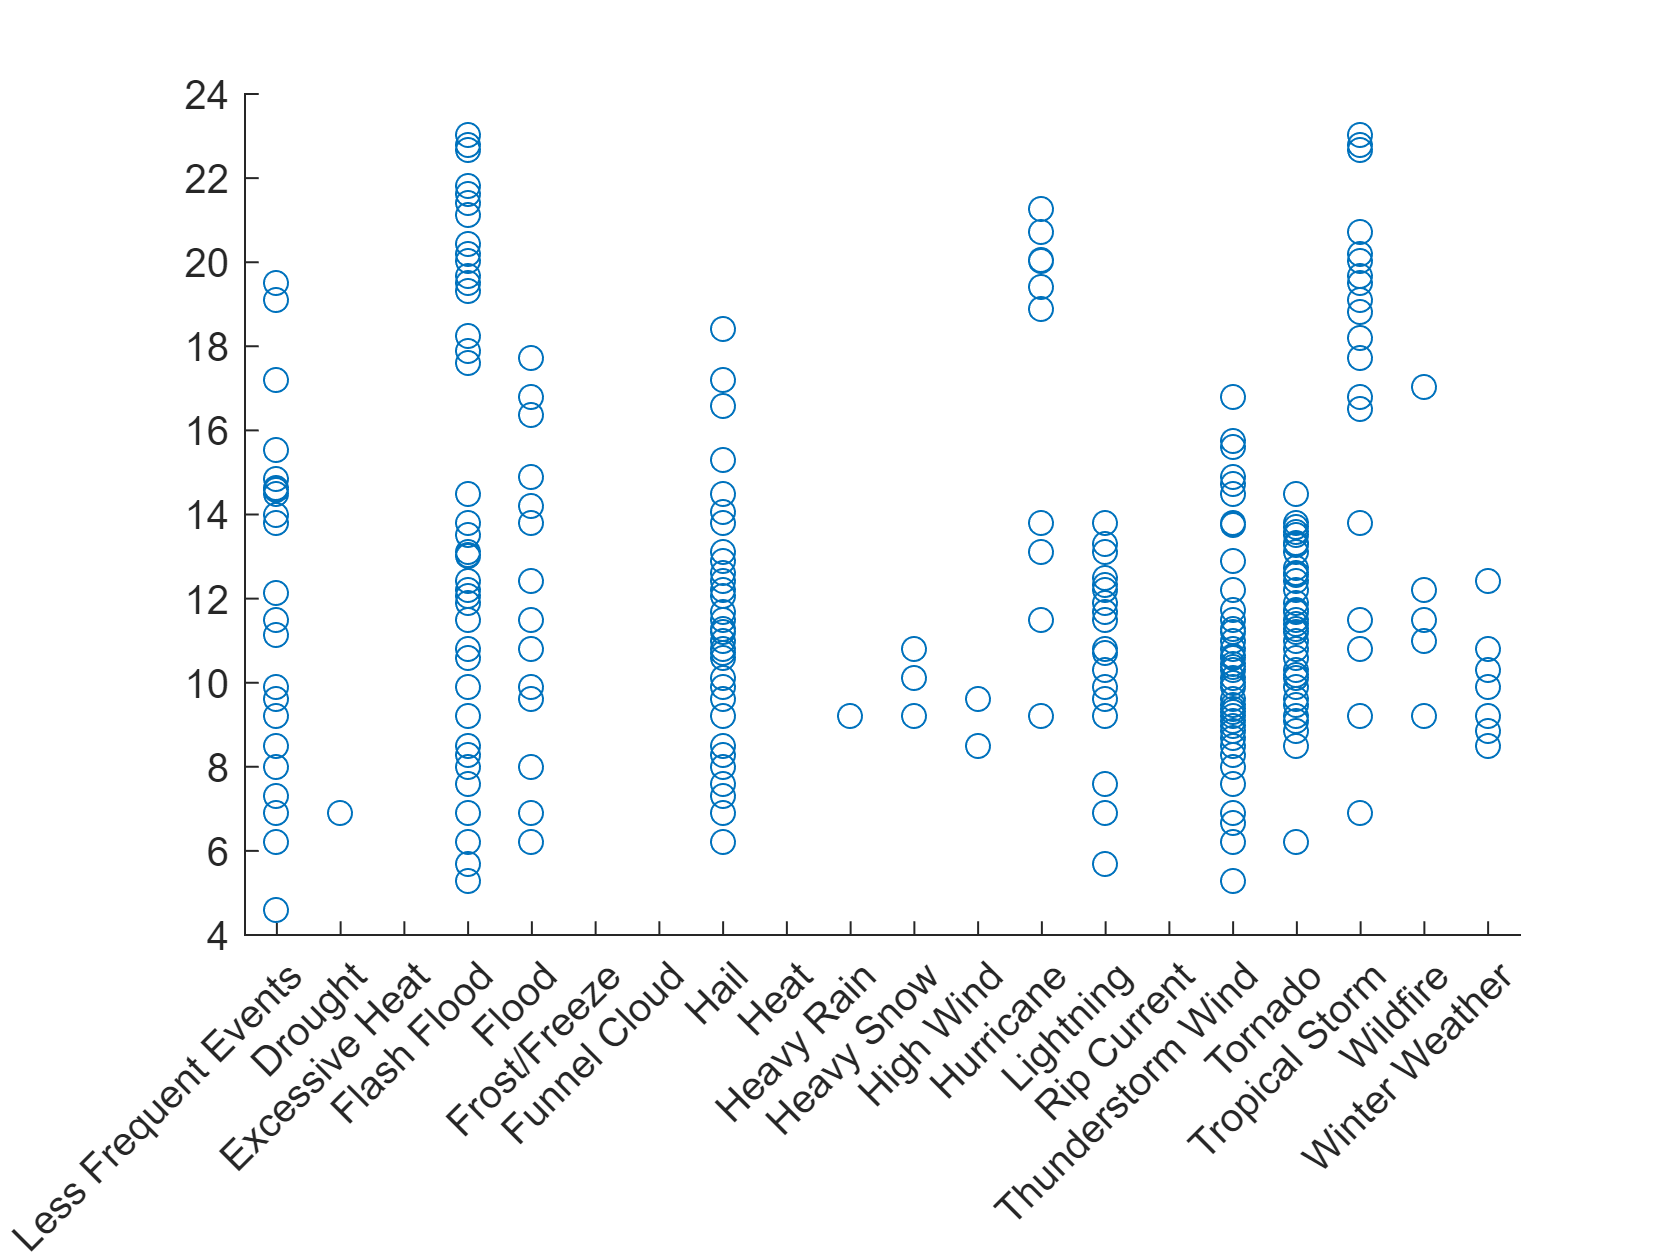

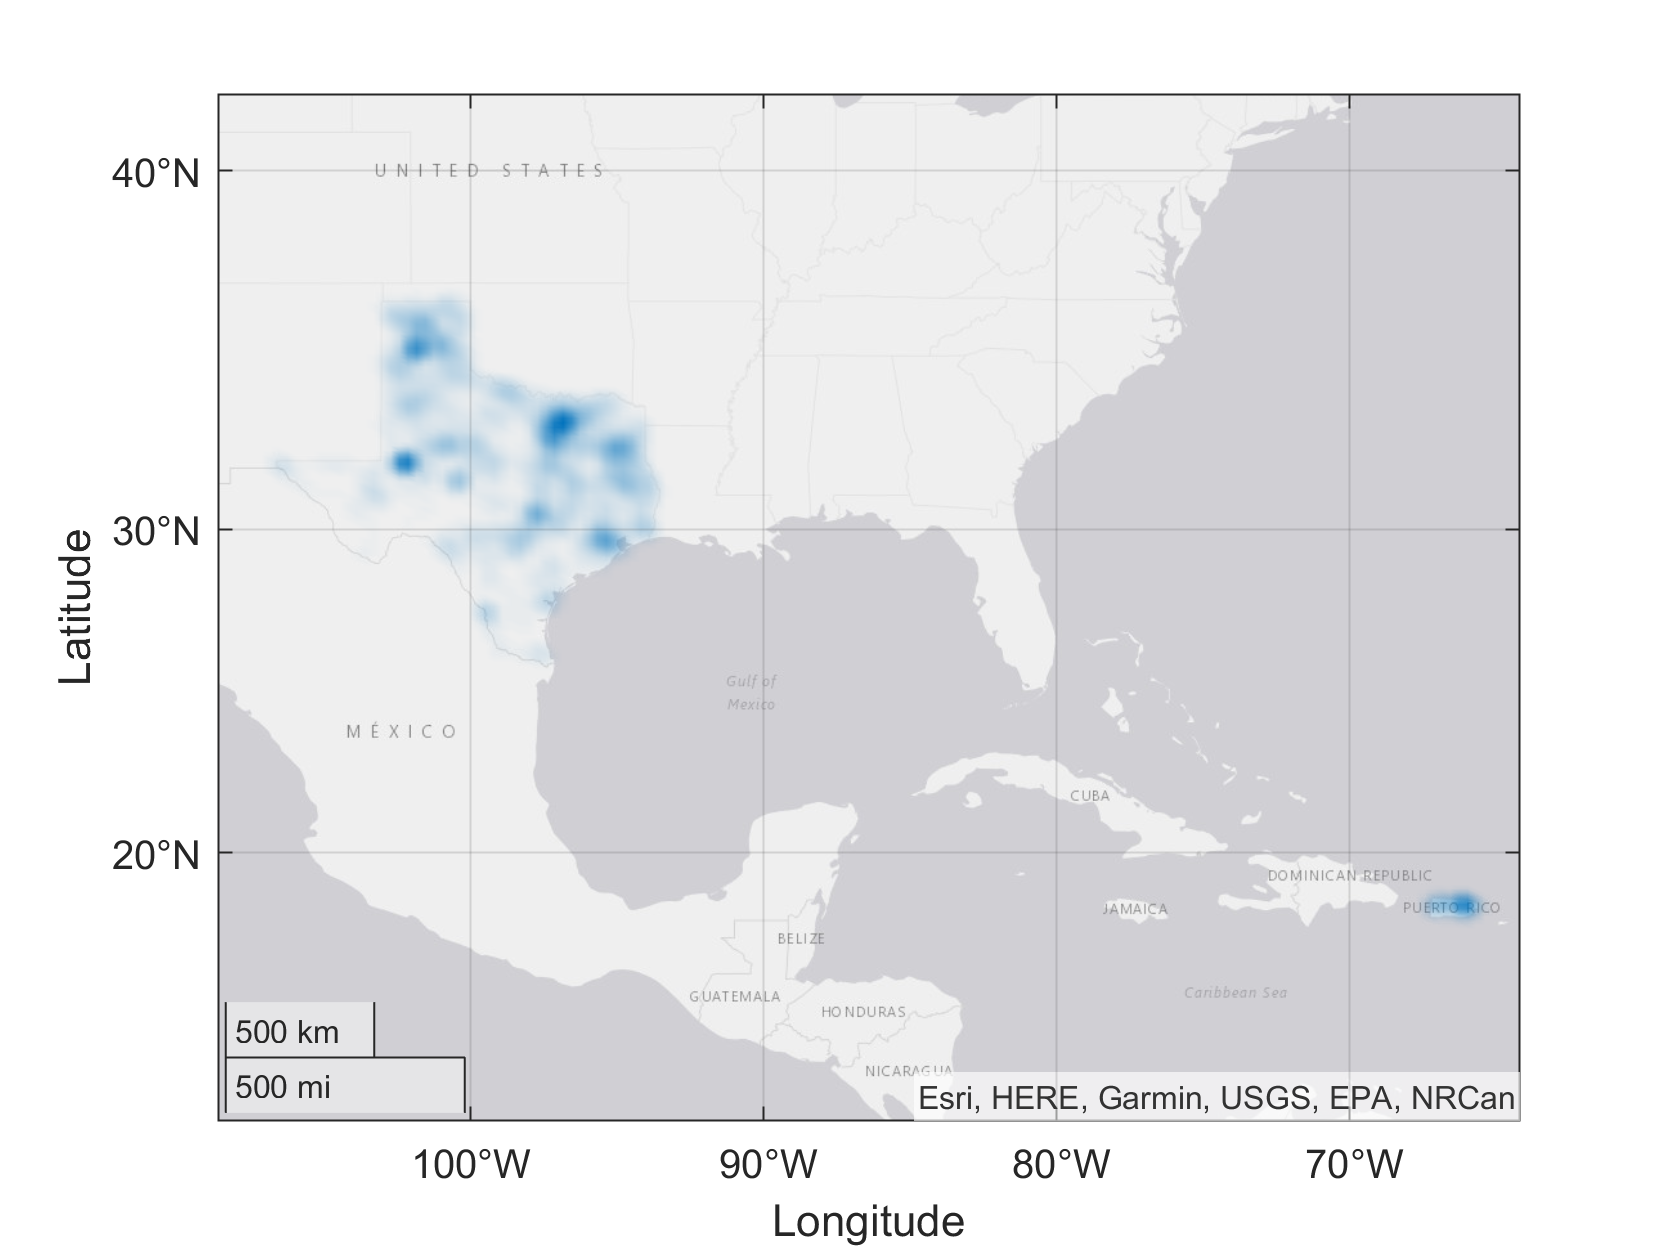

scatter(Data2.Event_Type,log(Data2.Total_Cost))

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

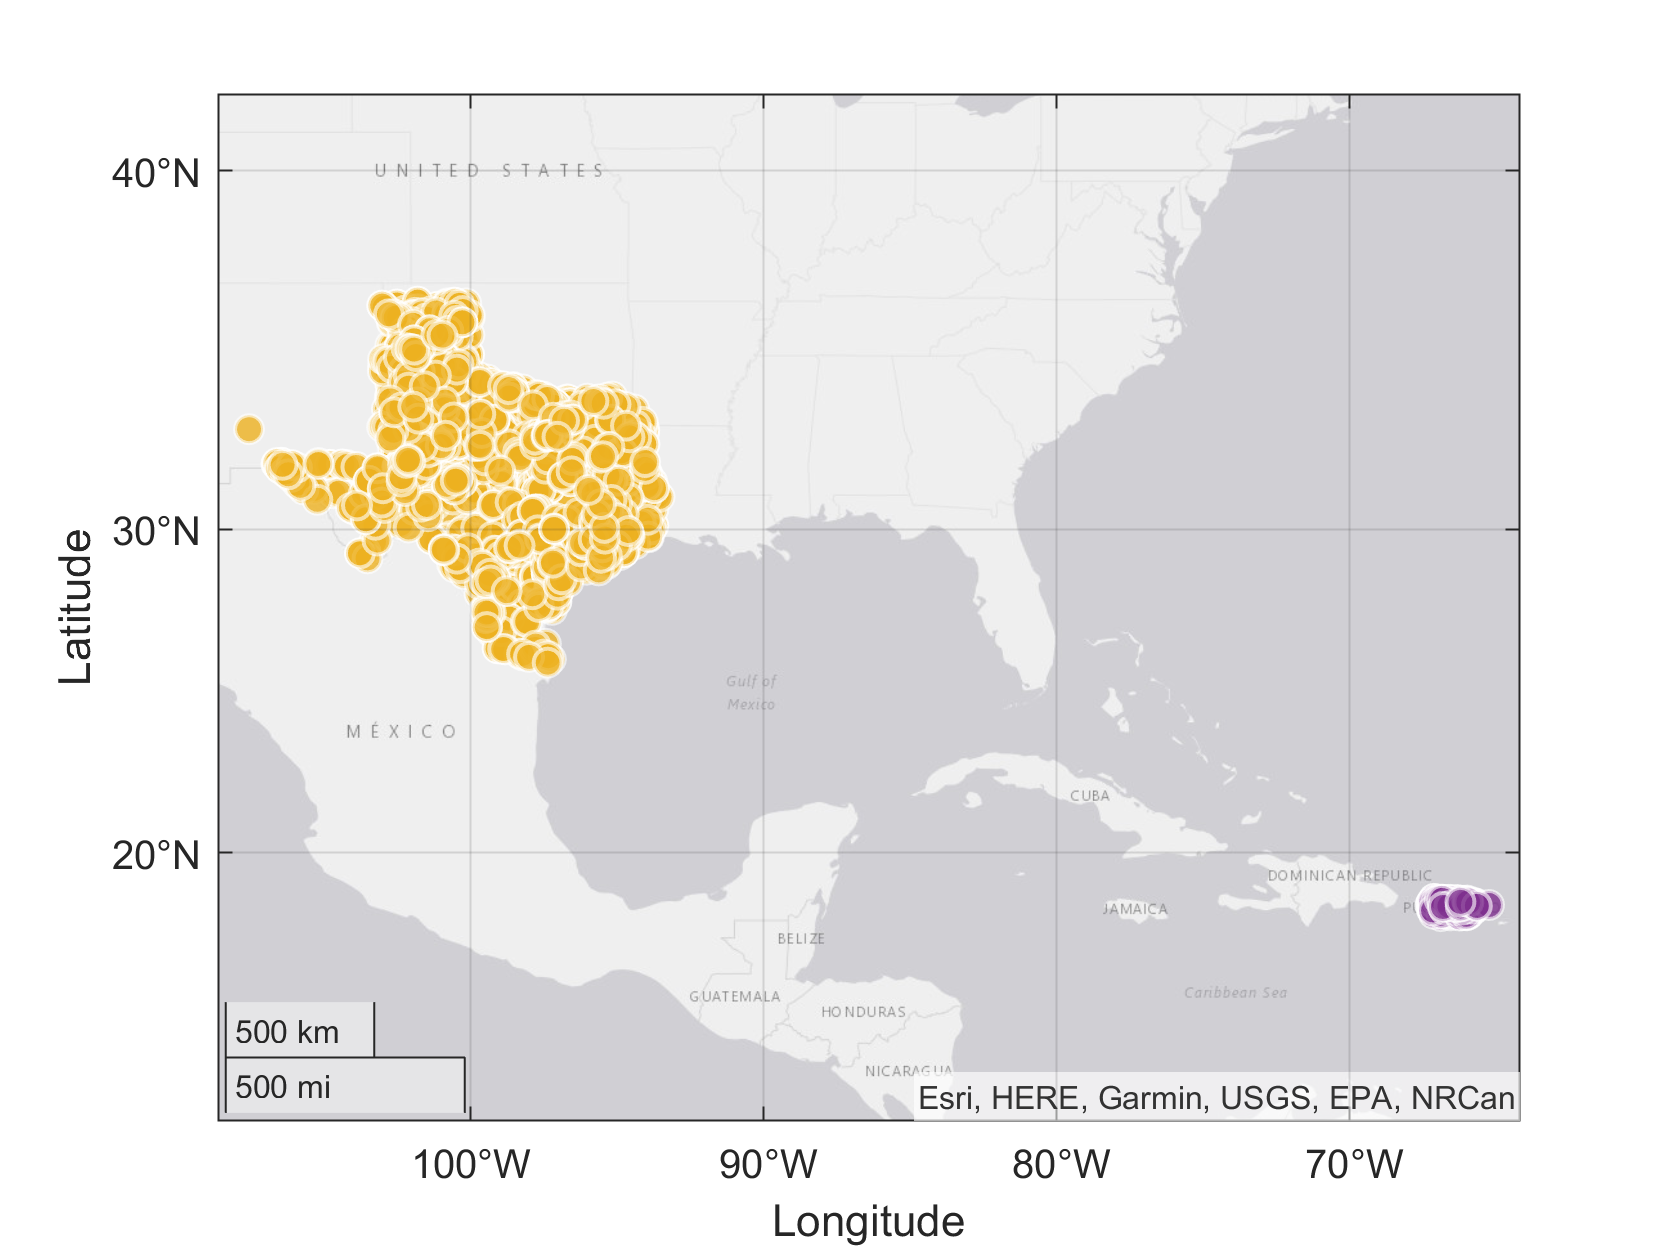

geobubble(Data2.Begin_Lat,Data2.Begin_Lon,ColorData=Data2.State)

## Analysis

### Three Counties with Most Events in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

Data3 = Data2(Data2.State =='TEXAS',:)

Data3 = 3628×25 table
    EpisodeID      Event_ID     State    Year     Month        Event_Type         CZ_Name       Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                 Episode_Narrative                                                                        

Data4 = Data3(ismember(Data3.CZ_Name,{'ANGELINA','ARMSTRONG','BANDERA'}),:)

Data4 = 67×25 table
    EpisodeID      Event_ID     State    Year     Month         Event_Type         CZ_Name       Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                            

- Angelina - 41

- Armstrong -15

- Bandera -11

### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

Data5 = Data2(Data2.State =='PUERTO RICO',:)

Data5 = sortrows(Data5,'CZ_Name');
Data5 = Data5(ismember(Data5.CZ_Name,{'GUAYNABO','MAYAGUEZ','NAGUABO','SAN JUAN'}),:)

Data5 = 222×25 table
    EpisodeID      Event_ID        State       Year      Month      Event_Type         CZ_Name           Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                   

- Mayaguez - 14

- San Juan - 13

- Guaynabo -  12

- Naguabo - 12

### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 1. *Be sure to include the dollar amount*. 

Data2;
Data6 = Data2(~ismissing(Data2.Property_Cost),:);
Data6 = Data6(Data6.State == 'TEXAS',:);
Data6 = Data6(Data6.Property_Cost~=0,:);
G1 = groupsummary(Data6,"CZ_Name","sum","Property_Cost")

G1 = 169×3 table
    CZ_Name     GroupCount    sum_Property_Cost
    ________    __________    _________________

    ANDERSON         1                 5000    
    ANDREWS          1                 6000    
    ANGELINA         1                1e+05    
    ARANSAS          7           1.9504e+09    
    ARCHER           1                 8000    
    AUSTIN           2              1.1e+06    
    BAILEY           3             4.22e+05    
    BASTROP          4            1.705e+06    
    BEE              8             5.15e+06    
    BELL             5              1.3e+05    
    BEXAR            3              3.1e+05    
    BLANCO           1                 5000    
    BORDEN           1                20000    
    BOSQUE           6             3.09e+05    
    BRAZORIA        11           2.0015e+09    
    BRAZOS           2              1.5e+07    


[G11,id11] = sort(G1.sum_Property_Cost,'descend');
G1 = G1(id11,:)

G1 = 169×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    GALVESTON           13                2e+10    
    FORT BEND           16           1.6006e+10    
    MONTGOMERY           2              1.4e+10    
    HARRIS              23           1.0002e+10    
    JEFFERSON            6                3e+09    
    BRAZORIA            11           2.0015e+09    
    ARANSAS              7           1.9504e+09    
    ORANGE               1              1.5e+09    
    NUECES              15           1.3016e+09    
    WALKER               6              1.2e+09    
    LIBERTY              2                1e+09    
    SAN JACINTO          2                7e+08    
    POLK                 4           6.0005e+08    
    HARDIN               2                6e+08    
    SAN PATRICIO         9            5.025e+08 

- Galveston   2*10^10 $

- Fort Bend    1.6*10^10 $

- Montgome   1.4*10^10 $

### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 2. *Be sure to include the dollar amount*. 

Data7 = Data2(~ismissing(Data2.Property_Cost),:);
Data7 = Data7(Data7.State == 'PUERTO RICO',:);
Data7 = Data7(Data7.Property_Cost~=0,:);
G2 = groupsummary(Data7,"CZ_Name","sum","Property_Cost");
[G22,id22] = sort(G2.sum_Property_Cost,'descend');
G2 = G2(id22,:)

G2 = 52×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    TOA BAJA            1               2.5e+09    
    ADJUNTAS            3            7.5076e+08    
    CANOVANAS           2             7.505e+08    
    CAGUAS              3            7.5035e+08    
    BAYAMON             3            7.5025e+08    
    ARECIBO             2            7.5025e+08    
    BARCELONETA         2            7.5025e+08    
    BARRANQUITAS        2            7.5025e+08    
    CAMUY               2            7.5025e+08    
    CAROLINA            2            7.5025e+08    
    CATANO              2            7.5025e+08    
    CEIBA               2            7.5025e+08    
    UTUADO              2             7.502e+08    
    AGUAS BUENAS        2            7.5018e+08    
    AGUADILLA           2               7.5e+08  

- Toa Baja 2.5 *10^10 $

- Adjuntas 75076*10^4 $

- Canovanas 7505*10^5 $

## Conclusions and Recommendations

Summarize your analysis. Make a recommendation supported by the data.

Based on data analysis, Texas and Puerto Rico are the most devastated states of US hit by hurricane Harvey, in 2017. 

Most of the resources should be spend in these two states. We have provided the list of most hit counties in these states.